# Rate Maps Performance

clear; close all; clc;
animalID = [65622,63383,67330,67456,66922,65588,67324,67141];
animals = length(animalID);

main_dir = get_data_root();
meta_table = readtable(fullfile(main_dir,'Metadata.xlsx'),"Sheet",'Data ID');


frame_rate = 0.02;
bin_width = 1;
smoothing = 2;
speed_threshold = 0.05; % 5 cm/s or 2.5 cm/s?
colors = {'#284B5E','#BC554C'};
mat_size = 100*100;

% define output variables
SI_high = cell(6,animals);
SI_low = cell(6,animals);
FR_low = cell(6,animals);
FR_high = cell(6,animals);

for a = 1:length(animalID)

    identity = [meta_table.animal_id,meta_table.experiment_type];
    date = cell2mat(meta_table.date);

    exp = find((identity(:,1) == animalID(a) & identity(:,2) == 2)+(identity(:,1)== animalID(a) & identity(:,2) == 3));
    [session,~] = size(date(exp,:));
    validity = meta_table.validity(exp);
    d = date(exp,:);


    for s = 1:session
        if validity(s) == 1

        d = date(exp(s),:);
        else

            continue
        end

        session_num = 'A';
        animal_ID = num2str(animalID(a));

        % load variables
        path = char(fullfile(main_dir,animal_ID,d,session_num,'data/Processed'));
        load(fullfile(path, 'postprocessed.mat'));
        load(fullfile(path, 'behavior.mat'));
        load(fullfile(path,'Position_tuning.mat'));

        % filter for valid cells (QM)
        trial_spikes = trial_spikes(2:end,valid_cells);
        [trials,cell_numb] = size(trial_spikes);

        index = find(strcmp(meta_table.date, d) == 1 & meta_table.animal_id == str2double(animal_ID));
        g = meta_table.genotype(index); % 1 = control, 2 = exp

        save_path = char(fullfile(main_dir,"Figures/Ingvild/Ephys/Ratemaps/Performance",animal_ID,char(d)));

        % separate into performance
        perfect_idx = error(:,1) == 0;
        spikes_perf = trial_spikes(perfect_idx,:);
        spikes_error = trial_spikes(~perfect_idx,:);
        fr = cellfun(@mean,firing_rate);

        FRerror = nan(trials,cell_numb);
        FRperf = nan(trials,cell_numb);

        FRerror(~perfect_idx,:) = fr(~perfect_idx,:);
        FRperf(perfect_idx,:) = fr(perfect_idx,:);


        firing_rate_avr = mean(cellfun(@mean,firing_rate));
        trial_position = trial_position(2:end);

        %%%%%%%%%%%%%%%%%%%%%%%%%% Ratemaps: all trials %%%%%%%%%%%%%%%%%%%%%%%%%% 

        spatial_info_content_perf = nan(1,cell_numb);
        spatial_info_content_error = nan(1,cell_numb);


        units = table2array(quality_metrics(:,1));
        unit_id = units(valid_cells');
        %%%%%%%%%%%%%%%%%%%%%%%%%% Error Trials %%%%%%%%%%%%%%%%%%%%%%%%%%
        for c = 1:cell_numb 
        
            cells = spikes_error(:, c);

            if firing_rate_avr(c)>= 15

                field_stats_error(c).unit = unit_id(c);
            else
        
            velocity_session = cell2mat(velocity(~perfect_idx));
            
            % separate into error and perfect trials

            spikes = cell2mat(cells');
                   
            if isempty(spikes)

                field_stats_error(c).unit = unit_id(c);
            else
                % 2,5 cm/s cut-off (velocity is in m/s)
                position = cell2mat(trial_position(~perfect_idx));
                    
                spikes_filtered = speed_filter(velocity_session,speed_threshold,position,spikes,frame_rate);
    
                % convert to cm: the function operates in cm
                position = [position(:,1) position(:,2).*100 position(:,3).*100];
                
                % From BNT
                map = analyses.map(position, spikes_filtered', 'smooth', smoothing, 'binWidth', bin_width,  'blanks', 'off','limits',[0 100 0 100]);
              
                rate_map_error(c).ratemap = map;
                rate_map_error(c).unit = unit_id(c);
  
    
                % Calculate Spatial Information
                [information, sparsity, selectivity] = mapStatsPDF(map);
    
                spatial_info_content_error(c) = information.content;
    
                
                f = figure('Visible','off');
                plot.colorMap(flip(map.z), flip(map.time));
                title(sprintf('Error: Rate Map Cell %d',c));
    
                fighandle = sprintf('Cell %d Error',c);
                save_figure(save_path,fighandle);
                
                % get some field specifications
    
                [fieldsMap, fields_struct] = placefield(map);
               
                field_stats_error(c).place_field = fields_struct;
                field_stats_error(c).unit = unit_id(c);
            end
            end
        end

        %%%%%%%%%%%%%%%%%%%%%%%%%% Perfect Trials %%%%%%%%%%%%%%%%%%%%%%%%%%
        if sum(perfect_idx) == 0
            field_stats_perf = [];
            rate_map_perf = [];

        else

            for c = 1:cell_numb 
            
                cells = spikes_perf(:, c);
    
                if firing_rate_avr(c)>= 15
    
                    field_stats_perf(c).unit = unit_id(c);
                else
            
                velocity_session = cell2mat(velocity(perfect_idx));
                
                % separate into error and perfect trials
    
                spikes = cell2mat(cells');
                       
                if isempty(spikes)
    
                    field_stats_perf(c).unit = unit_id(c);
                else
    
                    % 2,5 cm/s cut-off (velocity is in m/s)
                    position = cell2mat(trial_position(perfect_idx));
                        
                    spikes_filtered = speed_filter(velocity_session,speed_threshold,position,spikes,frame_rate);
        
                    % convert to cm: the function operates in cm
                    position = [position(:,1) position(:,2).*100 position(:,3).*100];
                    
                    % From BNT
                    map = analyses.map(position, spikes_filtered', 'smooth', smoothing, 'binWidth', bin_width,  'blanks', 'off','limits',[0 100 0 100]);
                  
                    rate_map_perf(c).ratemap = map;
                    rate_map_perf(c).unit = unit_id(c);
      
        
                    % Calculate Spatial Information
                    [information, sparsity, selectivity] = mapStatsPDF(map);
        
                    spatial_info_content_perf(c) = information.content;
                     
                    f = figure('Visible','off');
                    plot.colorMap(flip(map.z), flip(map.time));
                    title(sprintf('Perfect: Rate Map Cell %d',c));
        
                    fighandle = sprintf('Cell %d Perfect',c);
                    save_figure(save_path,fighandle);
                    
                    % get some field specifications
        
                    [fieldsMap, fields_struct] = placefield(map);
                   
                    field_stats_perf(c).place_field = fields_struct;
                    field_stats_perf(c).unit = unit_id(c);
                end
                end
            end
        end



        %%%%%%%%%%%%%%%%%%%%%%%%%% Save variables %%%%%%%%%%%%%%%%%%%%%%%%%%
    
        save(fullfile(path,'RateMapsPerformance.mat'),"rate_map_error","rate_map_perf","field_stats_error","field_stats_perf","spatial_info_content_error","spatial_info_content_perf", "mat_size");
        
        % clear variables so there is no turnover for next session
        clear("rate_map_error","rate_map_perf","field_stats_error","field_stats_perf");

        %%%%%%%%%%%%%%%%%%%%%%%%%% Compile data %%%%%%%%%%%%%%%%%%%%%%%%%%
        SI_high{s,a} = spatial_info_content_perf; 
        SI_low{s,a} = spatial_info_content_error;
        FR_low{s,a} = FRerror;
        FR_high{s,a} = FRperf;

    end
end
save(fullfile(main_dir,'CompiledData','SIperformance.mat'),"SI_low","SI_high","FR_low","FR_high");


## Compare SI Performance

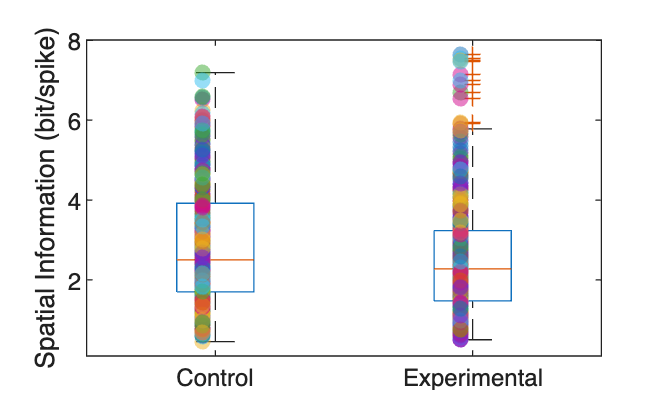

t-test p-value: 0.0003996


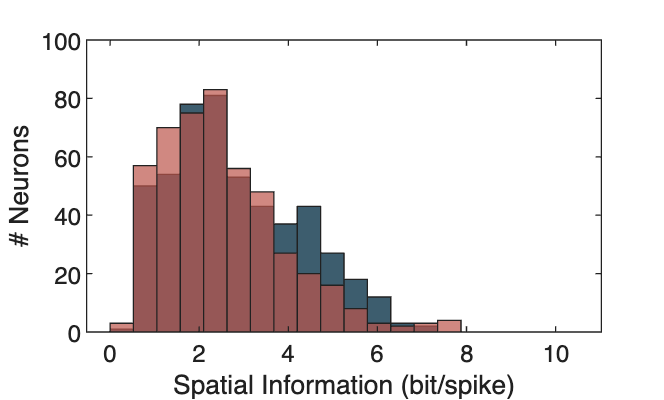

% data is compiled so you can place this in a separate script
load(fullfile(get_data_root(),'CompiledData','SIperformance.mat'));
control = [1,2,3,4];
experimental = [5,6,7,8];
cell_numb = [608,593];

label_text = 'Spatial Information (bit/spike)';
edges = linspace(0,10.5,21);
plot_group_comparison(SI_high, control, experimental, cell_numb, edges, colors, label_text, label_text);

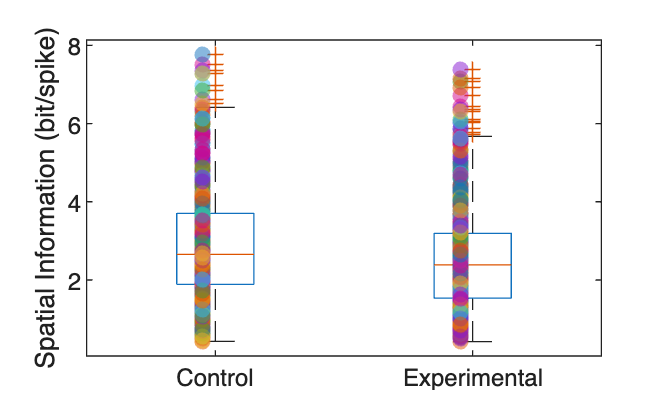

t-test p-value: 0.00020847


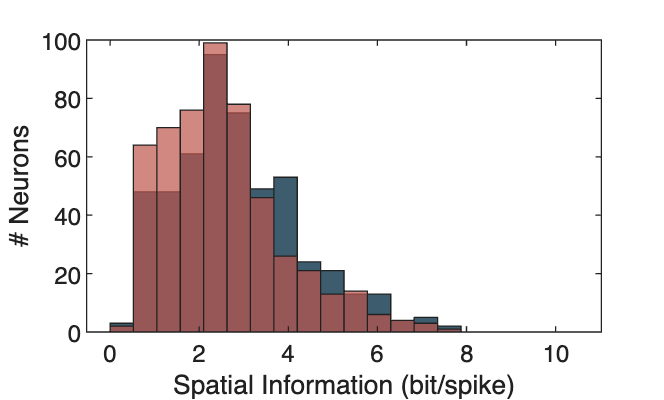


edges = linspace(0,10.5,21);
plot_group_comparison(SI_low, control, experimental, cell_numb, edges, colors, label_text, label_text);

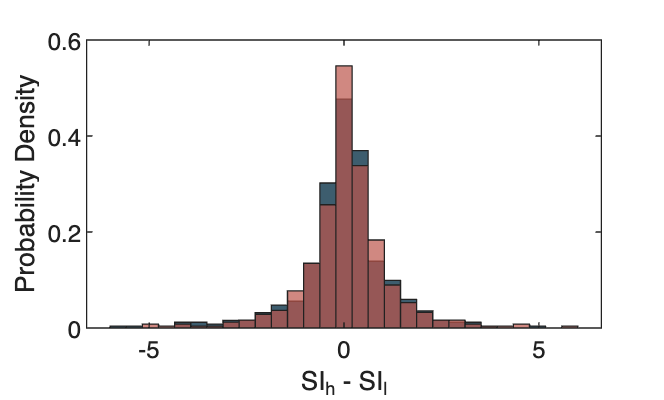


% % Compare control low vs high | experimental low vs high
% colors_exp = {'#700d13','#d01212'};
% colors_cont = {'#03045e','#00b4d8'};
% high = 1:4;
% low = 5:8;
% edges = linspace(0,10.5,21);
% control_performance = [SI_high(:,control),SI_low(:,control)];
% plot_group_comparison(control_performance, high, low, [cell_numb(1),cell_numb(1)], edges, colors_cont, label_text, label_text);
% 
% 
% edges = linspace(0,10.5,21);
% exp_performance = [SI_high(:,experimental),SI_low(:,experimental)];
% plot_group_comparison(exp_performance, high, low, [cell_numb(2),cell_numb(2)], edges, colors_exp, label_text, label_text);


% Get the distribution of difference in performance SI
SIh_exp = SI_high(:,experimental);
SIl_exp = SI_low(:,experimental);

SIh_exp = cell2mat(SIh_exp(:)');
SIl_exp = cell2mat(SIl_exp(:)');

d_exp = SIh_exp - SIl_exp;

SIh_cont = SI_high(:,control);
SIl_cont = SI_low(:,control);

SIh_cont = cell2mat(SIh_cont(:)');
SIl_cont = cell2mat(SIl_cont(:)');

d_cont = SIh_cont - SIl_cont;
edges = linspace(-6,6,30);
figure
histogram(d_cont,edges,'Normalization','pdf','FaceAlpha', 0.9, 'FaceColor', colors{1});
hold on
histogram(d_exp,edges,'Normalization','pdf','FaceAlpha', 0.7, 'FaceColor', colors{2});
xlabel('SI_h - SI_l')
ylabel('Probability Density')

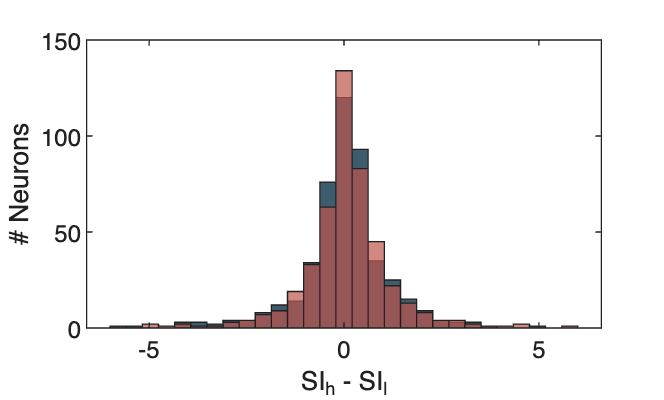


figure
histogram(d_cont,edges,'FaceAlpha', 0.9, 'FaceColor', colors{1});
hold on
histogram(d_exp,edges,'FaceAlpha', 0.7, 'FaceColor', colors{2});
xlabel('SI_h - SI_l')
ylabel('# Neurons')

figure_handle = 'Performance SI ratio';
% save_figure(fullfile(get_data_root(),'Figures/Ingvild/Ephys/SI/Comparison/SI'),figure_handle)

[~,p] = ttest2(d_cont,d_exp);

% Compare FR in high performance and low performance trials
% filter for cells that have an average FR above 20 Hz
fr_high_avr = cell(session,animals);

Unrecognized function or variable 'session'.

fr_low_avr = cell(session,animals);
ratio_fr = cell(session,animals); 
for a = 1:animals
    
    for s = 1:session
        fr_low = FR_low{s, a};
        fr_high = FR_high{s, a};
        if isempty(fr_low)
            continue
        end
        session_avr = nanmean([fr_low;fr_high]);
        
        exclude =  session_avr > 20 | session_avr < 0.05;

        if sum(exclude) == 0
            fr_high_avr{s,a} = mean(FR_high{s,a},'omitnan');
            fr_low_avr{s,a} = mean(FR_low{s,a},'omitnan');
            
            ratio_fr{s,a} = mean(FR_high{s,a},'omitnan')-mean(FR_low{s,a},'omitnan')

        end

        exclude_idx = find(exclude);
        for i = 1:sum(exclude)
            FR_low{s, a}(:,exclude_idx(i)) = nan(25,1);
            FR_high{s, a}(:,exclude_idx(i)) = nan(25,1);
        end
        fr_high_avr{s,a} = mean(FR_high{s,a},'omitnan');
        fr_low_avr{s,a} = mean(FR_low{s,a},'omitnan');
        
        ratio_fr{s,a} = mean(FR_high{s,a},'omitnan')-mean(FR_low{s,a},'omitnan')

    end
end
